## **Venus Fly Trap EP**

## **Section 1: Data Import and LPF**

Note: much of this code was written seperately, variable names may be inconsistent.

clear; clc; close all;

% Directory
input_dir = 'recordings';
output_dir = 'filtered_data';

if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% Get list of all .wav files
file_list = dir(fullfile(input_dir, '*.wav'));

if isempty(file_list)
    error('No .wav files found in "%s". Please check your folder path.', input_dir);
end

for k = 1:length(file_list)
    [~, fileName, fileExt] = fileparts(file_list(k).name);
    file_path = fullfile(input_dir, file_list(k).name);
    [y, Fs] = audioread(file_path);
    % Mono conversion
    if size(y, 2) > 1
        y = mean(y, 2);
    end
    % PSD Calculations for raw 
    N_raw = length(y);
    Y_raw = fft(y);
    pow_raw = (abs(Y_raw)/N_raw).^2;
    num_pts_raw = floor(N_raw/2) + 1;
    freq_raw = (0:num_pts_raw-1) * (Fs / N_raw);
    pow_raw_half = pow_raw(1:num_pts_raw);
    pow_raw_half(2:end-1) = 2 * pow_raw_half(2:end-1);

    % Downsample to 200 Hz
    target_Fs = 200;
    y = resample(y, target_Fs, Fs);
    Fs = target_Fs;

    % FIR Filter
    f_pass = 5; f_stop = 10; order = 150;
    Wpass = f_pass / (Fs/2);
    Wstop = f_stop / (Fs/2);
    b = firls(order, [0 Wpass Wstop 1], [1 1 0 0]);
    y_filtered = filtfilt(b, 1, y);
    new_filename = [fileName, 'filt', fileExt];
    output_path = fullfile(output_dir, new_filename);
    audiowrite(output_path, y_filtered, Fs);
    
    fprintf('Processed: %s -> %s\n', file_list(k).name, new_filename);
end

Processed: 2.2tap28s.wav -> 2.2tap28sfilt.wav
Processed: 2.2tap30s.wav -> 2.2tap30sfilt.wav
Processed: 2.2taps161412radoms.wav -> 2.2taps161412radomsfilt.wav
Processed: 2.2taps17s.wav -> 2.2taps17sfilt.wav
Processed: 2.2taps20s.wav -> 2.2taps20sfilt.wav
Processed: 2.2taps21s.wav -> 2.2taps21sfilt.wav
Processed: 2.2taps23s.wav -> 2.2taps23sfilt.wav
Processed: 2.2taps24s.wav -> 2.2taps24sfilt.wav
Processed: 2.2taps26s.wav -> 2.2taps26sfilt.wav
Processed: 2tap20s.wav -> 2tap20sfilt.wav
Processed: 2tap22s.wav -> 2tap22sfilt.wav
Processed: 2tap24s.wav -> 2tap24sfilt.wav
Processed: 2taps26s.wav -> 2taps26sfilt.wav
Processed: 2taps28s.wav -> 2taps28sfilt.wav
Processed: 2taps30s.wav -> 2taps30sfilt.wav
Processed: 2taps32s.wav -> 2taps32sfilt.wav
Processed: 2taps34s.wav -> 2taps34sfilt.wav
Processed: 2taps36s.wav -> 2taps36sfilt.wav
Processed: 2taps38s.wav -> 2taps38sfilt.wav
Processed: 2taps40s.wav -> 2taps40sfilt.wav
Processed: 3.2taps22sclosedtappedafterclose.wav -> 3.2taps22sclosedtappedaft


% Diagnostic Plots (For the last file processed)
fprintf('\nGenerating diagnostic plots for: %s\n', new_filename);


Generating diagnostic plots for: onetap2.4filt.wav


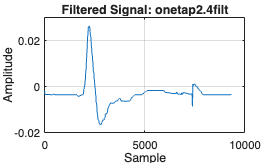


% Time Domain Plot
figure('Name', 'Filtered Signal');
plot(y_filtered)
title(['Filtered Signal: ', fileName, 'filt'])
xlabel('Sample'); ylabel('Amplitude'); grid on;

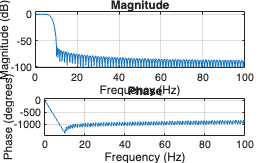


% Frequency Response
figure('Name', 'Filter Response');
freqz(b, 1, 1024, Fs)
xlim([0, 100])

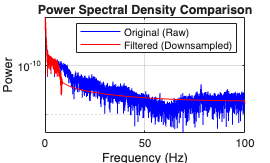


% PSD Comparison
N_f = length(y_filtered);
Y_f = fft(y_filtered);
pow_f = (abs(Y_f)/N_f).^2;
num_pts_f = floor(N_f/2) + 1;
freq_f = (0:num_pts_f-1) * (Fs / N_f);
pow_f_half = pow_f(1:num_pts_f);
pow_f_half(2:end-1) = 2 * pow_f_half(2:end-1);

figure('Name', 'PSD Comparison');
semilogy(freq_raw, pow_raw_half, 'b', 'DisplayName', 'Original (Raw)')
hold on
semilogy(freq_f, pow_f_half, 'r', 'DisplayName', 'Filtered (Downsampled)')
title('Power Spectral Density Comparison')
xlabel('Frequency (Hz)'); ylabel('Power');
xlim([0 100]); grid on; legend;

Cropping to form filters

## Cropping

crop_dir = 'cropped_data';  
filt_dir = output_dir;
crop_limit_sec = 22;             % Duration for cropping
fprintf('\nStarting Step 2: Cropping...\n');


Starting Step 2: Cropping...


filt_files = dir(fullfile(filt_dir, '*filt.wav'));

for i = 1:length(filt_files)
    [~, filtName, fileExt] = fileparts(filt_files(i).name);
    [y_filt, Fs_filt] = audioread(fullfile(filt_dir, filt_files(i).name));
    
    max_samples = round(crop_limit_sec * Fs_filt);
    
    if length(y_filt) > max_samples
        y_cropped = y_filt(1:max_samples, :);
    else
        y_cropped = y_filt;
    end
    
    crop_filename = [filtName, 'crop', fileExt];
    audiowrite(fullfile(crop_dir, crop_filename), y_cropped, Fs_filt);
    fprintf('Cropped: %s\n', crop_filename);
end

Cropped: 2.2tap28sfiltcrop.wav
Cropped: 2.2tap30sfiltcrop.wav
Cropped: 2.2taps161412radomsfiltcrop.wav
Cropped: 2.2taps17sfiltcrop.wav
Cropped: 2.2taps20sfiltcrop.wav
Cropped: 2.2taps21sfiltcrop.wav
Cropped: 2.2taps23sfiltcrop.wav
Cropped: 2.2taps24sfiltcrop.wav
Cropped: 2.2taps26sfiltcrop.wav
Cropped: 2tap20sfiltcrop.wav
Cropped: 2tap22sfiltcrop.wav
Cropped: 2tap24sfiltcrop.wav
Cropped: 2taps26sfiltcrop.wav
Cropped: 2taps28sfiltcrop.wav
Cropped: 2taps30sfiltcrop.wav
Cropped: 2taps32sfiltcrop.wav
Cropped: 2taps34sfiltcrop.wav
Cropped: 2taps36sfiltcrop.wav
Cropped: 2taps38sfiltcrop.wav
Cropped: 2taps40sfiltcrop.wav
Cropped: 3.2taps22sclosedtappedafterclosefiltcrop.wav
Cropped: 3.2taps24sfiltcrop.wav
Cropped: oneTap1filtcrop.wav
Cropped: oneTap2filtcrop.wav
Cropped: oneTap3filtcrop.wav
Cropped: oneTap4filtcrop.wav
Cropped: oneTap5filtcrop.wav
Cropped: oneTap6filtcrop.wav
Cropped: oneTap7filtcrop.wav
Cropped: onetap2.1filtcrop.wav
Cropped: onetap2.2filtcrop.wav
Cropped: onetap2.3filtcrop.


fprintf('\nGenerating diagnostic plots for last file...\n');


Generating diagnostic plots for last file...


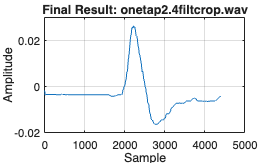


figure('Name', 'Filtered and Cropped Result');
plot(y_cropped)
title(['Final Result: ', crop_filename])
xlabel('Sample'); ylabel('Amplitude'); grid on;


disp('Check "filtered_data" and "cropped_data" folders.');

Check "filtered_data" and "cropped_data" folders.


## Creating AP Shape Correlation Filter

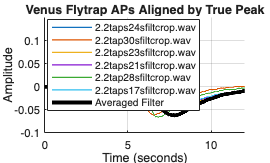

%% PEAK ALIGNMENT & AVERAGING
% Point this to the directory created in the previous step
input_dir_align = './cropped_data'; 

% Files to be used in AP waveform generation
file_list = {'2.2taps24sfiltcrop.wav', '2.2tap30sfiltcrop.wav', ...
             '2.2taps23sfiltcrop.wav', '2.2taps21sfiltcrop.wav', '2.2tap28sfiltcrop.wav',...
             '2.2taps17sfiltcrop.wav'}; 

Fs_align = 200; 
window_len = round(30 * Fs_align); 
aligned_APs = zeros(length(file_list), window_len);
time_axis = (0:window_len-1) / Fs_align;

% Force all peaks to sit at the 5-second mark
target_peak_idx = round(5.0 * Fs_align); 

figure('Name', 'Venus Flytrap AP Alignment');
hold on;

for i = 1:length(file_list)
    file_path = fullfile(input_dir_align, file_list{i});
    
    if exist(file_path, 'file')
        [y, ~] = audioread(file_path);
        if size(y, 2) > 1, y = mean(y, 2); end 
        
        [~, local_peak_idx] = max(y);
        shift_amount = target_peak_idx - local_peak_idx;
        if shift_amount >= 0
            shifted_y = [zeros(shift_amount, 1); y];
        else
            shifted_y = y(-shift_amount+1:end);
        end
        
        if length(shifted_y) >= window_len
            aligned_APs(i, :) = shifted_y(1:window_len);
        else
            aligned_APs(i, :) = [shifted_y; zeros(window_len - length(shifted_y), 1)];
        end
        
        plot(time_axis, aligned_APs(i, :), 'LineWidth', 1.0, 'DisplayName', file_list{i});
    else
        fprintf('Warning: File not found: %s\n', file_list{i});
    end
end

correlation_filter = mean(aligned_APs, 1) * 1.44;
plot(time_axis, correlation_filter, 'k', 'LineWidth', 3.0, 'DisplayName', 'Averaged Filter');

title('Venus Flytrap APs Aligned by True Peak');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('show', 'Location', 'best');
grid on;
xlim([0 12]);
hold off;


% Trim and Save
trim_seconds = 4.27;
trim_samples = round(trim_seconds * Fs_align);

if trim_samples < length(correlation_filter)
    correlation_filter = correlation_filter(trim_samples+1:22*Fs_align);
end


save("vftAP.mat", "correlation_filter");

latency = [.35 .6 .1 .11 .15 .15 .15];
meanLatency = mean(latency);
fprintf('Mean Latency: %.4f\n', meanLatency);

Mean Latency: 0.2300


## Calculate Remaining EP Shapes

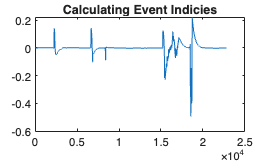

figure
input_dir = 'filtered_data';
file_name = '3.2taps22sclosedtappedafterclosefilt.wav'; 
file_path = fullfile(input_dir, file_name);
[realSignal, ~] = audioread(file_path);
if size(realSignal, 2) > 1, realSignal = mean(realSignal, 2); end 
realSignal = realSignal(:); 
time_vec = (0:length(realSignal)-1) * 1/Fs;
plot(realSignal)
title("Calculating Event Indicies")


closedResponse = realSignal(6562:15093);
digestRelease = realSignal(15093:end);


save("vftClose.mat", "closedResponse");

save("vftDigest.mat", "digestRelease");


## Venus Fly Trap Signal Detection & Performance Evaluator

clear; clc; close all;

fs = 200;
dt = 1/fs;
latency = 0.023; 

% Update ground truth for the specific file you are testing
% [APs_Expected Closure_Expected(1/0) Digest_Expected(1/0)]
ground_truth_matrix = [4 1 1]; 

% Point to the filtered/cropped file from the previous step
input_dir = 'filtered_data';
file_name = '3.2taps22sclosedtappedafterclosefilt.wav'; 


file_path = fullfile(input_dir, file_name);

% Load Templates (Generated in previous steps)
load('vftAP.mat', 'correlation_filter'); 
try
    load('vftClose.mat', 'closedResponse');
catch
    closedResponse = zeros(size(correlation_filter)); % Placeholder if missing
end
try
    load('vftDigest.mat', 'digestRelease');
catch
    digestRelease = zeros(size(correlation_filter)); % Placeholder if missing
end

% Zero-Mean and Normalize Templates
temp_AP = correlation_filter(:) - mean(correlation_filter);
temp_Close = closedResponse(:) - mean(closedResponse);
temp_Digest = digestRelease(:) - mean(digestRelease);

temp_AP = temp_AP / (norm(temp_AP) + eps);
temp_Close = temp_Close / (norm(temp_Close) + eps);
temp_Digest = temp_Digest / (norm(temp_Digest) + eps);

% Load Real Experimental Signal
if ~exist(file_path, 'file')
    error('File not found: %s. Check your "cropped_data" folder.', file_path);
end
[realSignal, ~] = audioread(file_path);
if size(realSignal, 2) > 1, realSignal = mean(realSignal, 2); end 
realSignal = realSignal(:); 
time_vec = (0:length(realSignal)-1) * dt;

% Get rolling local energy
local_energy_AP = sqrt(conv(realSignal.^2, ones(length(temp_AP), 1), 'same'));
local_energy_Close = sqrt(conv(realSignal.^2, ones(length(temp_Close), 1), 'same'));
local_energy_Digest = sqrt(conv(realSignal.^2, ones(length(temp_Digest), 1), 'same'));

% Calculate raw convolutions
raw_corr_AP = conv(realSignal, flip(temp_AP), 'same');
raw_corr_Close = conv(realSignal, flip(temp_Close), 'same');
raw_corr_Digest = conv(realSignal, flip(temp_Digest), 'same');

% Normalize scores
corr_AP = raw_corr_AP ./ (local_energy_AP * norm(temp_AP) + eps);
corr_Close = raw_corr_Close ./ (local_energy_Close * norm(temp_Close) + eps);
corr_Digest = raw_corr_Digest ./ (local_energy_Digest * norm(temp_Digest) + eps);

% Event Detection Thresholds
thresh_AP = 0.35;       
thresh_Close = 0.7; 
thresh_Digest = 0.45;

% Minimum distance adjusted for 200 Hz
min_dist_AP = 0.5 * fs; 
min_dist_Close = 2.0 * fs;
min_dist_Digest = 3.0 * fs;

[pks_AP, locs_AP] = findpeaks(corr_AP, 'MinPeakHeight', thresh_AP, 'MinPeakDistance', min_dist_AP);
[pks_Close, locs_Close] = findpeaks(corr_Close, 'MinPeakHeight', thresh_Close, 'MinPeakDistance', min_dist_Close);
[pks_Digest, locs_Digest] = findpeaks(corr_Digest, 'MinPeakHeight', thresh_Digest, 'MinPeakDistance', min_dist_Digest);


% Get peak times in seconds
peak_times_AP = locs_AP * dt;
peak_times_Close = locs_Close * dt;
peak_times_Digest = locs_Digest * dt;

% Adjust to event start times
start_times_AP = peak_times_AP - (round(length(temp_AP)/2) * dt);
start_times_Close = peak_times_Close - (round(length(temp_Close)/2) * dt);
start_times_Digest = peak_times_Digest - (round(length(temp_Digest)/2) * dt);

% --- 1. Digestion must happen after trap closure ---
if ~isempty(start_times_Close) && ~isempty(start_times_Digest)
    valid_digest_idx = start_times_Digest > start_times_Close(1);
    start_times_Digest = start_times_Digest(valid_digest_idx);
    locs_Digest = locs_Digest(valid_digest_idx);
    pks_Digest = pks_Digest(valid_digest_idx);
end

% --- 2. Snap Digestion to an AP & Hard Cutoff for AP Detection ---
if ~isempty(start_times_Digest) && ~isempty(start_times_AP)
    % Find the AP closest to the detected digestion start
    [~, closest_ap_idx] = min(abs(start_times_AP - start_times_Digest(1)));
    
    % Snap Digestion start to that specific AP
    digestion_start_time = start_times_AP(closest_ap_idx);
    start_times_Digest = digestion_start_time;
    
    % Keep only the first digestion event
    locs_Digest = locs_Digest(1);
    pks_Digest = pks_Digest(1);
    
    % CRITICAL: WIPE OUT all APs that occur AFTER the digestion starts.
    % Only APs up to and including the one that triggered digestion are kept.
    valid_ap_mask = start_times_AP <= digestion_start_time;
    
    start_times_AP = start_times_AP(valid_ap_mask);
    locs_AP = locs_AP(valid_ap_mask);
    pks_AP = pks_AP(valid_ap_mask);
end

% Infer Stimulus Times (only for valid APs)
inferred_stimuli = start_times_AP - latency;
%Eval
model_output = [length(start_times_AP), ~isempty(start_times_Close), ~isempty(start_times_Digest)];

fprintf('\n--- Model Performance Evaluation: %s ---\n', file_name);


--- Model Performance Evaluation: 3.2taps22sclosedtappedafterclosefilt.wav ---


fprintf('Ground Truth: APs: %d | Closure: %d | Digest: %d\n', ground_truth_matrix(1), ground_truth_matrix(2), ground_truth_matrix(3));

Ground Truth: APs: 4 | Closure: 1 | Digest: 1


fprintf('Model Output: APs: %d | Closure: %d | Digest: %d\n', model_output(1), model_output(2), model_output(3));

Model Output: APs: 3 | Closure: 1 | Digest: 1



if all(model_output == ground_truth_matrix)
    fprintf('Result: PERFECT MATCH (100%% Accuracy)\n');
else
    fprintf('Result: MISMATCH DETECTED.\n');
end

Result: MISMATCH DETECTED.


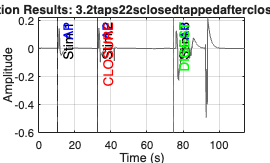


% Plot
figure('Name', 'Main Signal Detection', 'Color', 'w');
plot(time_vec, realSignal, 'Color', [0.4 0.4 0.4]); hold on;
for i = 1:length(inferred_stimuli)
    xline(inferred_stimuli(i), '--k', sprintf('Stim %d', i));
end
for i = 1:length(start_times_AP), xline(start_times_AP(i), '-b', 'AP'); end
for i = 1:length(start_times_Close), xline(start_times_Close(i), '-r', 'CLOSURE'); end
for i = 1:length(start_times_Digest), xline(start_times_Digest(i), '-g', 'DIGEST'); end
title(['Detection Results: ', file_name]); xlabel('Time (s)'); ylabel('Amplitude');
grid on; hold off;

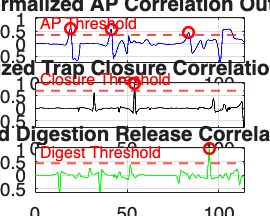


% Troubleshooting plots (same as your template)
% ... [Insert Subplots 1-3 from your template here] ...

figure('Name', 'Correlation Filter Troubleshooting', 'Color', 'w', 'Position', [150, 150, 1000, 800]);

% --- Font Size Controls ---
ax_fontsize = 14;    % Size for the axes tick numbers
label_fontsize = 14; % Size for the X and Y labels
title_fontsize = 16; % Size for the Subplot titles
yline_fontsize = 12; % Size for the threshold text

% --- Subplot 1: Action Potential ---
subplot(3, 1, 1);
plot(time_vec, corr_AP, 'b', 'LineWidth', 1); hold on;
yline(thresh_AP, 'r--', 'AP Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', yline_fontsize);
plot(locs_AP * dt, pks_AP, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
title('Normalized AP Correlation Output', 'FontWeight', 'bold', 'FontSize', title_fontsize);
ylabel('Shape Match Score', 'FontWeight', 'bold', 'FontSize', label_fontsize); 
grid on; hold off;
ylim([-inf,1.05])
set(gca, 'FontSize', ax_fontsize); % Applies font size to the axes ticks

% --- Subplot 2: Trap Closure ---
subplot(3, 1, 2);
plot(time_vec, corr_Close, 'k', 'LineWidth', 1); hold on;
yline(thresh_Close, 'r--', 'Closure Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', yline_fontsize);
plot(locs_Close * dt, pks_Close, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
title('Normalized Trap Closure Correlation Output', 'FontWeight', 'bold', 'FontSize', title_fontsize);
ylabel('Shape Match Score', 'FontWeight', 'bold', 'FontSize', label_fontsize); 
grid on; hold off;
ylim([-inf,1.05])
set(gca, 'FontSize', ax_fontsize);

% --- Subplot 3: Digestion ---
subplot(3, 1, 3);
plot(time_vec, corr_Digest, 'g', 'LineWidth', 1); hold on;
yline(thresh_Digest, 'r--', 'Digest Threshold', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', yline_fontsize);
plot(locs_Digest * dt, pks_Digest, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
title('Normalized Digestion Release Correlation Output', 'FontWeight', 'bold', 'FontSize', title_fontsize);
xlabel('Time (seconds)', 'FontWeight', 'bold', 'FontSize', label_fontsize);
ylabel('Shape Match Score', 'FontWeight', 'bold', 'FontSize', label_fontsize); 
grid on; hold off;
ylim([-inf,1.05])
set(gca, 'FontSize', ax_fontsize);

## Generative Model

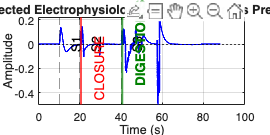

clear; clc; close all;

% --- Declarations & User Inputs ---
num_stimuli = input('Enter the number of stimuli: ');
stim_times = zeros(1, num_stimuli);
for i = 1:num_stimuli
    stim_times(i) = input(sprintf('Enter time for stimulus %d (in seconds): ', i)); 
end
stim_times = sort(stim_times);

% --- Constants ---
latency = 0.023;        
closure_threshold = 22; 
latencyTrap = 0.5;      
fs = 200;               
dt = 1/fs;

% --- Load Templates ---
load('vftAP.mat', 'correlation_filter');
load('vftClose.mat', 'closedResponse');
load('vftDigest.mat', 'digestRelease');

ap_shape = reshape(correlation_filter, 1, []);
closedResponse = reshape(closedResponse, 1, []);
digestRelease = reshape(digestRelease, 1, []);

% --- Initialize Signal Vector ---
max_wave_duration = max([length(ap_shape), length(closedResponse), length(digestRelease)]) * dt;
exp_length = max(stim_times) + latency + latencyTrap + max_wave_duration + 5; 
time_vec = 0:dt:exp_length;
signal_vec = zeros(size(time_vec));

% --- Build the Signal ---
trap_closed = false;
digestion_started = false;
closure_time = NaN;
digestion_indices = []; 

for i = 1:num_stimuli
    
    % 1. Add the Action Potential
    if ~digestion_started
        start_t = stim_times(i) + latency;
        idx1 = round(start_t / dt) + 1;
        idx2 = idx1 + length(ap_shape) - 1;
        
        if idx2 <= length(signal_vec)
            % REPLACEMENT instead of ADDITION
            % This preserves negative values but prevents stacking
            signal_vec(idx1:idx2) = ap_shape;
        end
    end
    
    % 2. Handle Transitions and Mechanical Responses
    if ~trap_closed
        if i > 1 && (stim_times(i) - stim_times(i-1)) <= closure_threshold
            trap_closed = true;
            closure_time = stim_times(i) + latency;
            
            c_start = closure_time + latencyTrap;
            c_idx1 = round(c_start / dt) + 1;
            c_idx2 = c_idx1 + length(closedResponse) - 1;
            
            if c_idx2 <= length(signal_vec)
                % Replace the segment with the closure response
                signal_vec(c_idx1:c_idx2) = closedResponse;
            end
        end
        
    elseif trap_closed && ~digestion_started
        digestion_started = true;
        digestion_indices = [digestion_indices, i]; 
        
        d_start = stim_times(i) + latency + latencyTrap; 
        digestion_start_time = d_start; % Capture the exact moment digestion signal begins
        d_idx1 = round(d_start / dt) + 1;
        d_idx2 = d_idx1 + length(digestRelease) - 1;
        
        if d_idx2 <= length(signal_vec)
            % Replace the segment with the digestion response
            signal_vec(d_idx1:d_idx2) = digestRelease;
        end
    end
end

% --- Plotting ---
figure('Name', 'Venus Fly Trap - Corrected Waveform', 'Color', 'w', 'Position', [100, 100, 1000, 500]);
plot(time_vec, signal_vec, 'b', 'LineWidth', 1.2);
hold on;
yline(0, 'k:', 'HandleVisibility', 'off'); % Baseline reference

% Labels
for i = 1:num_stimuli
    xline(stim_times(i), '--k', sprintf('S%d', i), 'Alpha', 0.4);
end

if trap_closed
    xline(closure_time + latencyTrap, '-r', 'CLOSURE', 'LineWidth', 1.5);
end
if digestion_started
    xline(digestion_start_time, '-g', 'DIGESTION START', ...
        'LineWidth', 1.5, 'Color', [0 0.5 0], ...
        'LabelVerticalAlignment', 'bottom', 'FontWeight', 'bold');
end

xlabel('Time (s)'); ylabel('Amplitude');
title('Corrected Electrophysiology: Negative Phases Preserved');
grid on; hold off;